# P2rY1 IHC analysis

defaultDir = 'M:\Projects And Analysis\Papers\P2ry1\Fig - IHCs'

defaultDir = 'M:\Projects And Analysis\Papers\P2ry1\Fig - IHCs'

cd(defaultDir);
% addpath(genpath('Matlab scripts'));
% cd('IHC figure');

% P6-P8 WT IHC apex MRS application for freq, amp analysis, 6mMK+ external
[mrs1, time1] = loadPclampData('2018_08_22_0005 whole file baseline mrs 25min.abf');

** abfload
opening 2018_08_22_0005 whole file baseline mrs 25min.abf..
data were acquired in gap-free mode


[mrs2, time2] = loadPclampData('2018_08_22_0007 whole file baseline mrs 2500.abf');

** abfload
opening 2018_08_22_0007 whole file baseline mrs 2500.abf..
data were acquired in gap-free mode


[mrs3, time3] = loadPclampData('2018_08_22_0013 mrs 20 min whole file adjusted.abf');

** abfload
opening 2018_08_22_0013 mrs 20 min whole file adjusted.abf..
data were acquired in gap-free mode


[mrs4, time4] = loadPclampData('2018_08_28_0011  whole file adjusted real.abf');

** abfload
opening 2018_08_28_0011  whole file adjusted real.abf..
data were acquired in gap-free mode


[mrs5, time5] = loadPclampData('2018_08_29_0003 whole file adjusted.abf');

** abfload
opening 2018_08_29_0003 whole file adjusted.abf..
data were acquired in gap-free mode


[mrs6, time6] = loadPclampData('2018_11_01_0008_baseline.abf');

** abfload
opening 2018_11_01_0008_baseline.abf..
data were acquired in gap-free mode


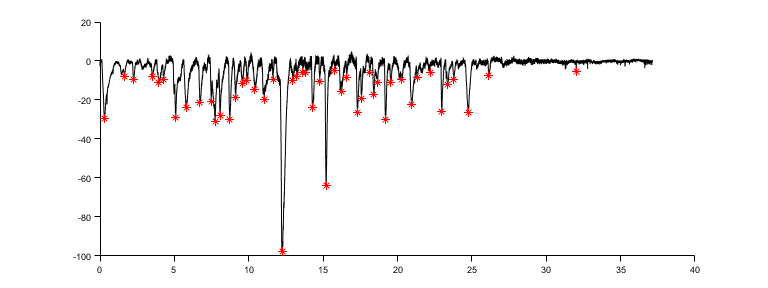

preFreq1 = 1.6000

postFreq1 = 0.1000

preAmp1 = -15.5981

postAmp1 = -5.4652


[preFreq1,postFreq1,preAmp1,postAmp1] = freqAmpIHC(mrs1,time1,27)

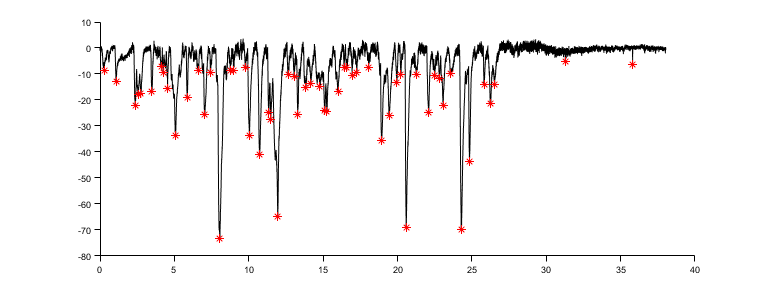

preFreq2 = 1.8000

postFreq2 = 0.2000

preAmp2 = -23.5048

postAmp2 = -5.7540

[preFreq2,postFreq2,preAmp2,postAmp2] = freqAmpIHC(mrs2,time2,27)

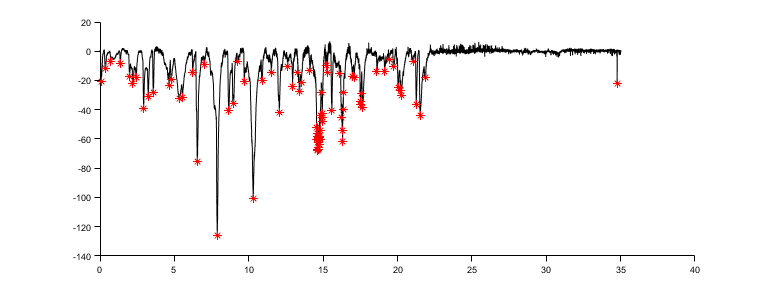

preFreq3 = 5.5000

postFreq3 = 0

preAmp3 = -38.4498

postAmp3 = 0

[preFreq3,postFreq3,preAmp3,postAmp3] = freqAmpIHC(mrs3,time3,22)

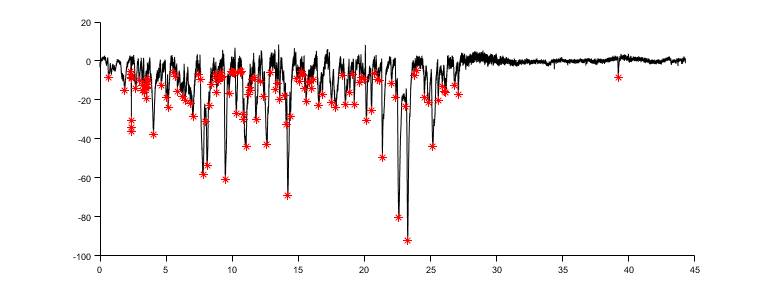

preFreq4 = 3.2000

postFreq4 = 0

preAmp4 = -21.7580

postAmp4 = 0

[preFreq4,postFreq4,preAmp4,postAmp4] = freqAmpIHC(mrs4,time4,27.5)

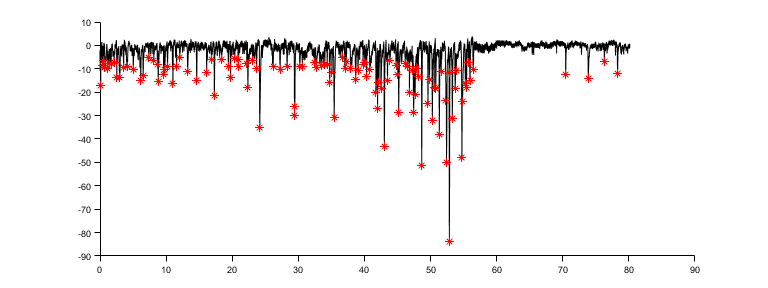

preFreq5 = 2.9000

postFreq5 = 0.1000

preAmp5 = -23.7076

postAmp5 = -10.3079

[preFreq5,postFreq5,preAmp5,postAmp5] = freqAmpIHC(mrs5,time5,56)

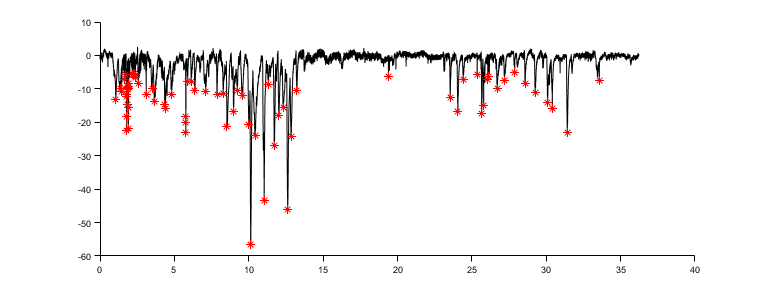

preFreq6 = 2.9000

postFreq6 = 0.2000

preAmp6 = -18.7442

postAmp6 = -8.4621

[preFreq6,postFreq6,preAmp6,postAmp6] = freqAmpIHC(mrs6,time6,13)


preMRSFreq = [preFreq1,preFreq2,preFreq3,preFreq4,preFreq5,preFreq6];
postMRSFreq = [postFreq1,postFreq2,postFreq3,postFreq4,postFreq5,postFreq6];

preMRSAmp = abs([preAmp1,preAmp2,preAmp3,preAmp4,preAmp5,preAmp6]);
postMRSAmp = abs([postAmp1,postAmp2,postAmp3,postAmp4,postAmp5,postAmp6]);

conditions = {'baseline','MRS2500'};
ylbl1 = 'Events per minute';
ylbl2 = 'Mean amplitude (-pA)';
dim = [2 3];
[hFreq pFreq] =compare2(preMRSFreq,postMRSFreq,conditions,ylbl1,dim);

    0.0046



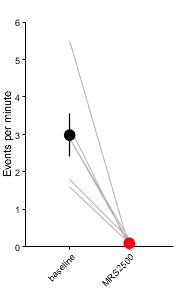

 ylim([0 6]);

%export_fig('.\EPS Panels\IHCMRSFreq.eps',gcf);  

[hAmp pAmp] =compare2(preMRSAmp,postMRSAmp,conditions,ylbl2,dim);

    0.0080



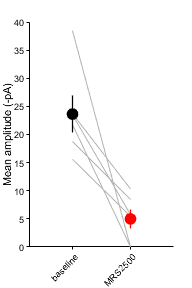

 ylim([0 40]);

%export_fig('.\EPS Panels\IHCMRSAmp',gcf);  


%travis modifications for figure
conditions = {'Basline','+MRS2500'};
h1 =compare2P(preMRSFreq',postMRSFreq',conditions,ylbl1,dim,[10 15]);

    0.0046



xtickangle(45);
 ylim([0 6]);
 yticks(0:2:6)
 yticklabels({'0','2','4','6'})
 figQuality(gcf,gca,[1.0 1.3])

h2 =compare2P(preMRSAmp',postMRSAmp',conditions,ylbl2,dim,[10 15]);

    0.0080



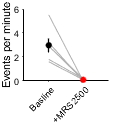

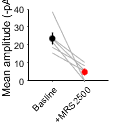

 ylim([0 40]);
 xtickangle(45);
 yticks(0:10:40);
  yticklabels({'0','10','20','30','40'})
 figQuality(gcf,gca,[1.0 1.2])
  figQuality(gcf,gca,[1.0 1.3]) 
handleTheSubplot({h1,h2},[1 2]);

figQuality(gcf,gca,[1.5 1.5]);
export_fig('.\EPS Panels\events_amplitude.eps')

figure;
[mrs1, time1] = loadPclampData('2018_08_22_0007.abf');

** abfload
opening 2018_08_22_0007.abf..
data were acquired in gap-free mode


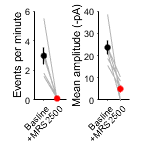

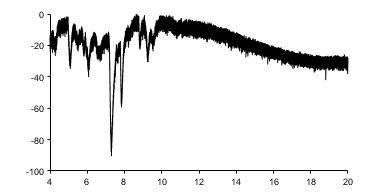

timeDrug = 27; %in minutes
newMrs1 = mrs1(time1 >= (timeDrug - 10)*60 & time1 <= (timeDrug + 10)*60);
newTime1 = time1(time1 >= (timeDrug - 10)*60 & time1 <= (timeDrug + 10)*60)/60;
newTime1 = newTime1 - newTime1(1);
plot(newTime1,newMrs1,'Color','k');
xlim([4 20])
figQuality(gcf,gca,[4 2]);
export_fig('.\EPS Panels\exMRSIHC.eps')

% P6-P8 WT IHC, apex MRS application, measuring current induction
[mrs1, time1] = loadPclampData('2018_08_22_0005.abf');

** abfload
opening 2018_08_22_0005.abf..
data were acquired in gap-free mode


[mrs2, time2] = loadPclampData('2018_08_22_0007.abf');

** abfload
opening 2018_08_22_0007.abf..
data were acquired in gap-free mode


[mrs3, time3] = loadPclampData('2018_08_22_0013.abf');

** abfload
opening 2018_08_22_0013.abf..
data were acquired in gap-free mode


[mrs4, time4] = loadPclampData('2018_08_28_0011.abf');

** abfload
opening 2018_08_28_0011.abf..
data were acquired in gap-free mode


[mrs5, time5] = loadPclampData('2018_08_29_0003.abf');

** abfload
opening 2018_08_29_0003.abf..
data were acquired in gap-free mode


[mrs6, time6] = loadPclampData('2018_11_01_0008.abf');

** abfload
opening 2018_11_01_0008.abf..
data were acquired in gap-free mode



[acsf1, time1_1] = loadPclampData('2018_08_22_0009.abf');

** abfload
opening 2018_08_22_0009.abf..
data were acquired in gap-free mode


[acsf2, time2_1] = loadPclampData('2018_08_22_0011.abf');

** abfload
opening 2018_08_22_0011.abf..
data were acquired in gap-free mode


[acsf3, time3_1] = loadPclampData('2018_08_30_0004.abf');

** abfload
opening 2018_08_30_0004.abf..
data were acquired in gap-free mode


[acsf4, time4_1] = loadPclampData('2018_08_30_0006.abf');

** abfload
opening 2018_08_30_0006.abf..
data were acquired in gap-free mode


[acsf5, time5_1] = loadPclampData('2018_10_11_0016.abf');

** abfload
opening 2018_10_11_0016.abf..
data were acquired in gap-free mode



[mrscs1, time1cs] = loadPclampData('2018_09_13_0002.abf');

** abfload
opening 2018_09_13_0002.abf..
data were acquired in gap-free mode


[mrscs2, time2cs] = loadPclampData('2018_09_13_0006.abf');

** abfload
opening 2018_09_13_0006.abf..
data were acquired in gap-free mode


[mrscs3, time3cs] = loadPclampData('2018_09_24_0005.abf');

** abfload
opening 2018_09_24_0005.abf..
data were acquired in gap-free mode


[mrscs4, time4cs] = loadPclampData('2018_10_04_0000.abf');

** abfload
opening 2018_10_04_0000.abf..
data were acquired in gap-free mode


[mrscs5, time5cs] = loadPclampData('2018_10_04_0002.abf');

** abfload
opening 2018_10_04_0002.abf..
data were acquired in gap-free mode


[mrscs6, time6cs] = loadPclampData('2018_10_04_0003.abf');

** abfload
opening 2018_10_04_0003.abf..
data were acquired in gap-free mode



[acsfcs1, time1_2] = loadPclampData('2018_09_21_0000.abf');

** abfload
opening 2018_09_21_0000.abf..
data were acquired in gap-free mode


[acsfcs2, time2_2] = loadPclampData('2018_09_21_0001.abf');

** abfload
opening 2018_09_21_0001.abf..
data were acquired in gap-free mode


[acsfcs3, time3_2] = loadPclampData('2018_09_21_0002.abf');

** abfload
opening 2018_09_21_0002.abf..
data were acquired in gap-free mode


[acsfcs4, time4_2] = loadPclampData('2018_10_04_0005.abf');

** abfload
opening 2018_10_04_0005.abf..
data were acquired in gap-free mode


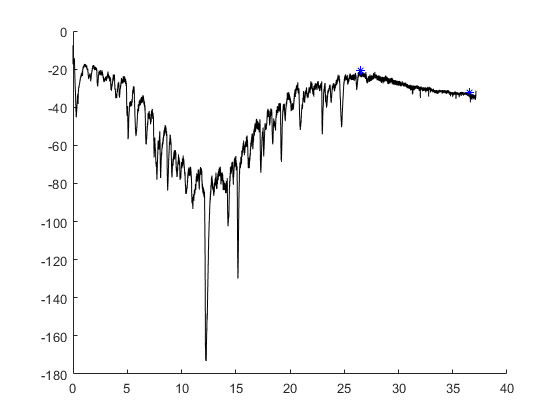

curChange1 = -11.3220

baselineMax1 = -20.8435

endMax1 = -32.1655


% change in holding current analysis

[curChange1,baselineMax1,endMax1] = currentAnalysisIHC(mrs1,time1,26.5,10)

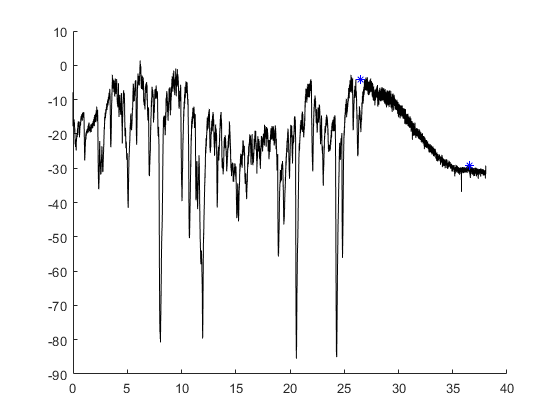

curChange2 = -25.1465

baselineMax2 = -4.1199

endMax2 = -29.2664

[curChange2,baselineMax2,endMax2] = currentAnalysisIHC(mrs2,time2,26.5,10)

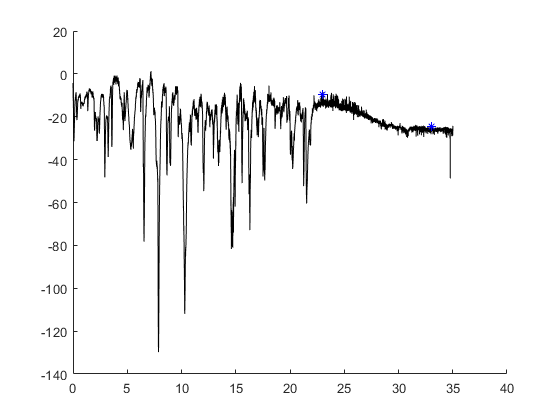

curChange3 = -15.0452

baselineMax3 = -9.4910

endMax3 = -24.5361

[curChange3,baselineMax3,endMax3] = currentAnalysisIHC(mrs3,time3,23,10)

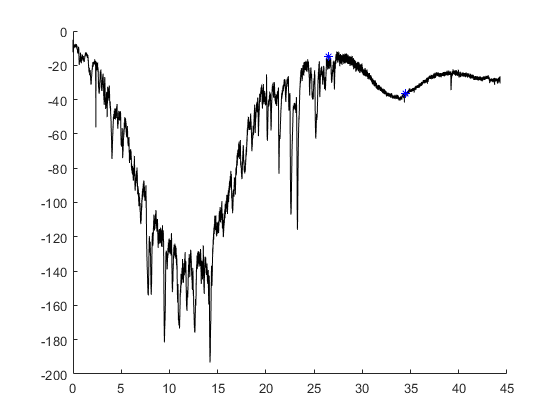

curChange4 = -21.2402

baselineMax4 = -15.1062

endMax4 = -36.3464

[curChange4,baselineMax4,endMax4] = currentAnalysisIHC(mrs4,time4,26.5,8)

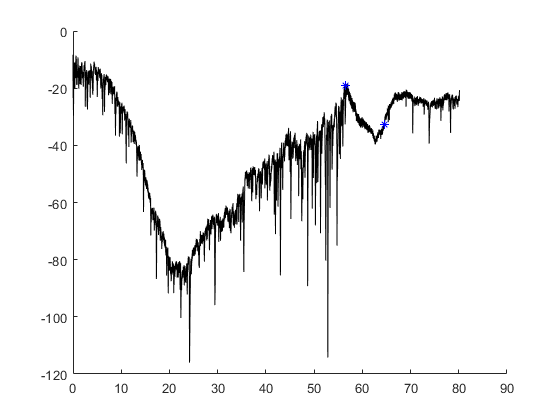

curChange5 = -13.5498

baselineMax5 = -19.1040

endMax5 = -32.6538

[curChange5,baselineMax5,endMax5] = currentAnalysisIHC(mrs5,time5,56.5,8)

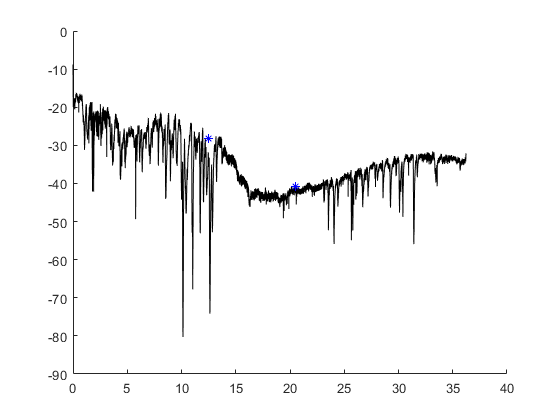

curChange6 = -12.5732

baselineMax6 = -28.3203

endMax6 = -40.8936

[curChange6,baselineMax6,endMax6] = currentAnalysisIHC(mrs6,time6,12.5,8)

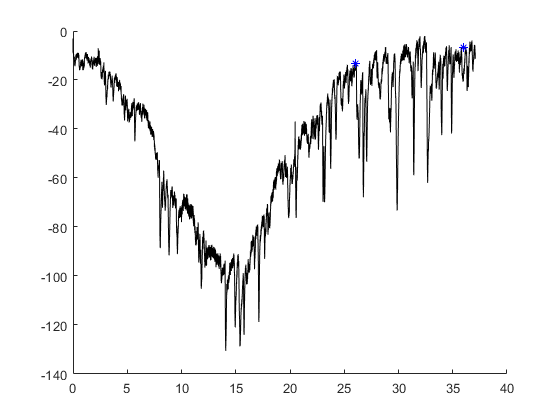

curChangeACSF1 = 6.3629

baselineMaxACSF1 = -13.1073

endMaxACSF1 = -6.7444


curChangeMRS = [curChange1,curChange2,curChange3,curChange4,curChange5,curChange6];
baselineMaxMRS = [baselineMax1,baselineMax2,baselineMax3,baselineMax4,baselineMax5,baselineMax6];
endMaxMRS = [endMax1,endMax2,endMax3,endMax4,endMax5,endMax6];

[curChangeACSF1,baselineMaxACSF1,endMaxACSF1] = currentAnalysisIHC(acsf1,time1_1,26,10)

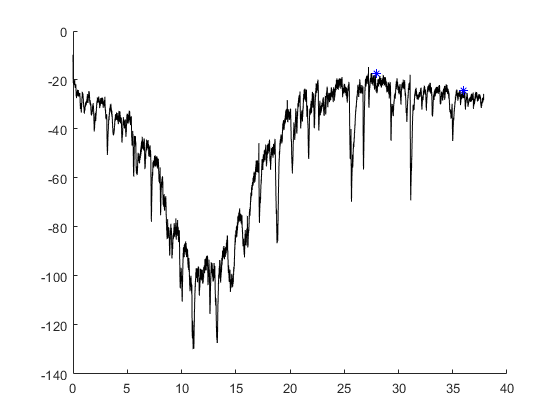

curChangeACSF2 = -7.0496

baselineMaxACSF2 = -17.1814

endMaxACSF2 = -24.2310

[curChangeACSF2,baselineMaxACSF2,endMaxACSF2] = currentAnalysisIHC(acsf2,time2_1,28,8)

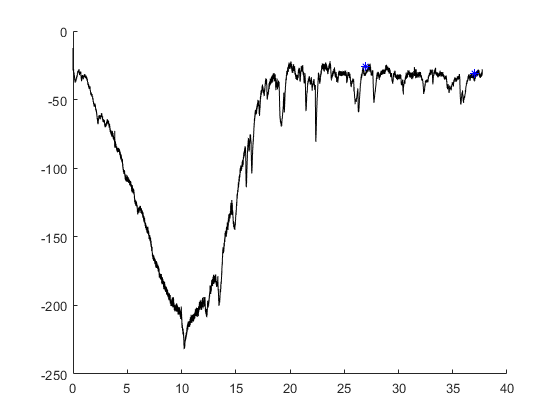

curChangeACSF3 = -4.6997

baselineMaxACSF3 = -26.0620

endMaxACSF3 = -30.7617

[curChangeACSF3,baselineMaxACSF3,endMaxACSF3] = currentAnalysisIHC(acsf3,time3_1,27,10)

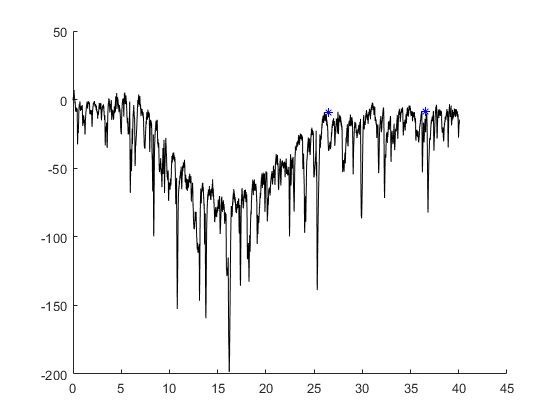

curChangeACSF4 = 0.3662

baselineMaxACSF4 = -9.0942

endMaxACSF4 = -8.7280

[curChangeACSF4,baselineMaxACSF4,endMaxACSF4] = currentAnalysisIHC(acsf4,time4_1,26.5,10)

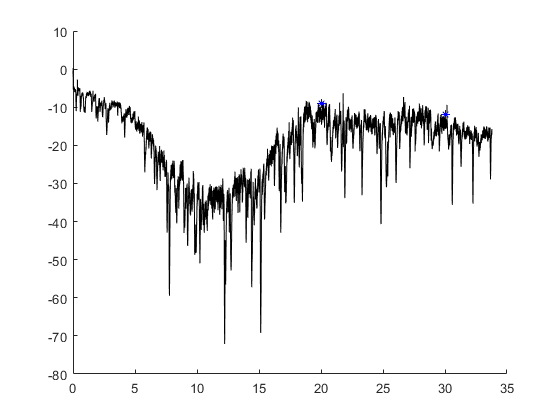

curChangeACSF5 = -3.0212

baselineMaxACSF5 = -8.9111

endMaxACSF5 = -11.9324

[curChangeACSF5,baselineMaxACSF5,endMaxACSF5] = currentAnalysisIHC(acsf5,time5_1,20,10)

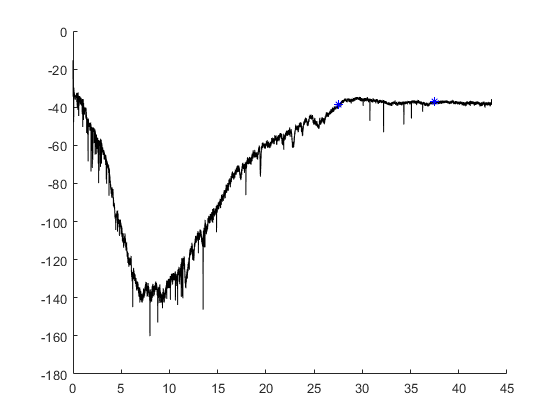

curChange1cs = 2.0599

baselineMax1cs = -38.8031

endMax1cs = -36.7432


curChangeACSF = [curChangeACSF1,curChangeACSF2,curChangeACSF3,curChangeACSF4,curChangeACSF5];
baselineMaxACSF = [baselineMaxACSF1,baselineMaxACSF2,baselineMaxACSF3,baselineMaxACSF4,baselineMaxACSF5];
endMaxACSF = [endMaxACSF1,endMaxACSF2,endMaxACSF3,endMaxACSF4,endMaxACSF5];

[curChange1cs,baselineMax1cs,endMax1cs] = currentAnalysisIHC(mrscs1,time1cs,27.5,10)

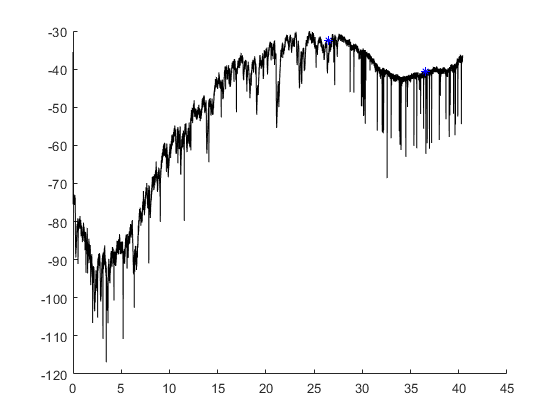

curChange2cs = -7.8735

baselineMax2cs = -32.6233

endMax2cs = -40.4968

[curChange2cs,baselineMax2cs,endMax2cs] = currentAnalysisIHC(mrscs2,time2cs,26.5,10)

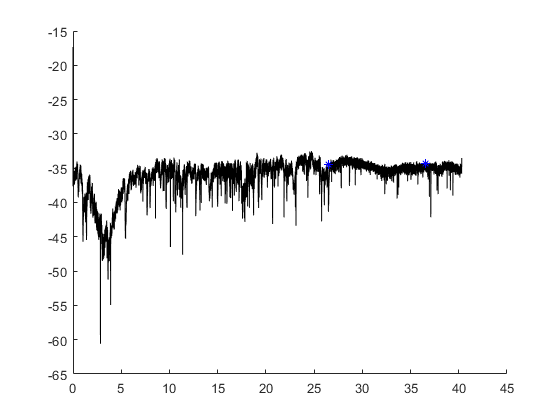

curChange3cs = 0.1221

baselineMax3cs = -34.3933

endMax3cs = -34.2712

[curChange3cs,baselineMax3cs,endMax3cs] = currentAnalysisIHC(mrscs3,time3cs,26.5,10)

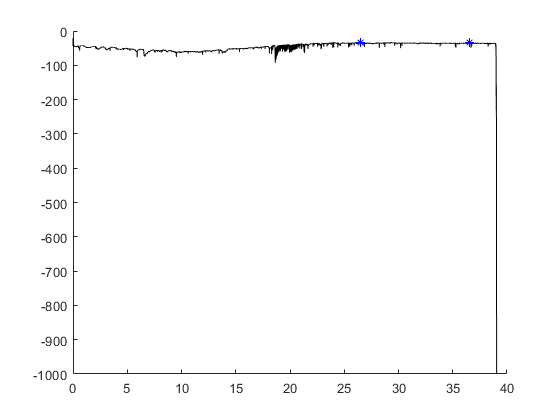

curChange4cs = -1.2512

baselineMax4cs = -33.2031

endMax4cs = -34.4543

[curChange4cs,baselineMax4cs,endMax4cs] = currentAnalysisIHC(mrscs4,time4cs,26.5,10)

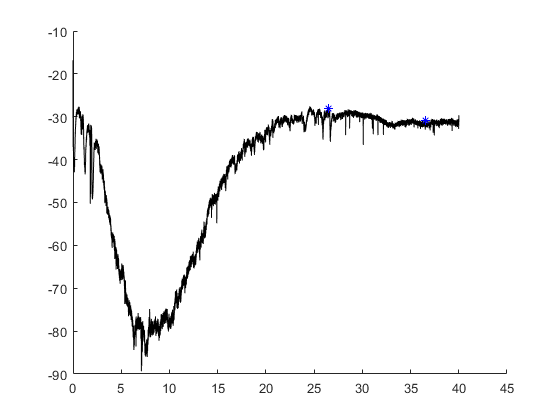

curChange5cs = -2.7008

baselineMax5cs = -28.0762

endMax5cs = -30.7770

[curChange5cs,baselineMax5cs,endMax5cs] = currentAnalysisIHC(mrscs5,time5cs,26.5,10)

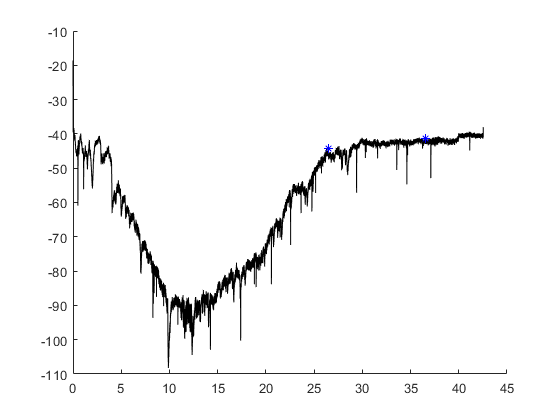

curChange6cs = 2.8839

baselineMax6cs = -44.2963

endMax6cs = -41.4124

[curChange6cs,baselineMax6cs,endMax6cs] = currentAnalysisIHC(mrscs6,time6cs,26.5,10)

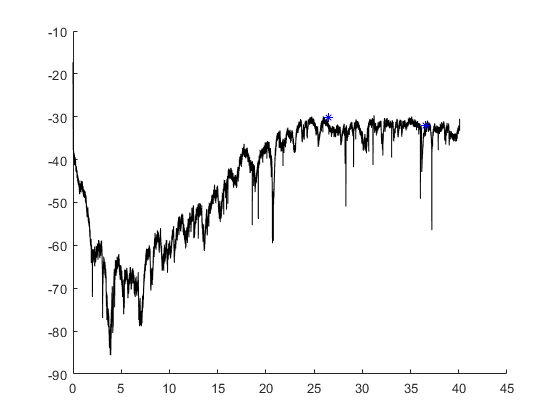

curChangeACSFcs1 = -1.8311


curChangeMRScs = [curChange1cs,curChange2cs,curChange3cs,curChange4cs,curChange5cs,curChange6cs];
baselineMaxcs = [baselineMax1cs,baselineMax2cs,baselineMax3cs,baselineMax4cs,baselineMax5cs,baselineMax6cs];
endMaxcs = [endMax1cs,endMax2cs,endMax3cs,endMax4cs,endMax5cs,endMax6cs];

[curChangeACSFcs1] = currentAnalysisIHC(acsfcs1,time1_2,26.5,10)

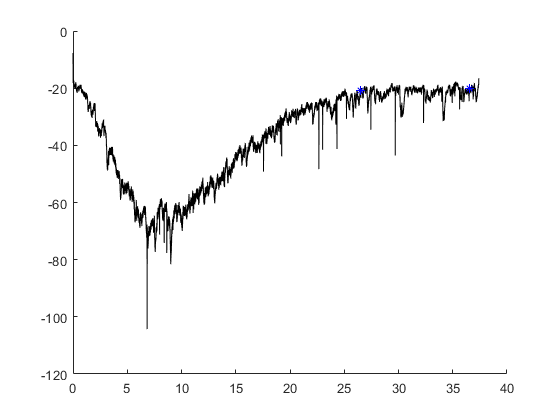

curChangeACSFcs2 = 0.4730

[curChangeACSFcs2] = currentAnalysisIHC(acsfcs2,time2_2,26.5,10)

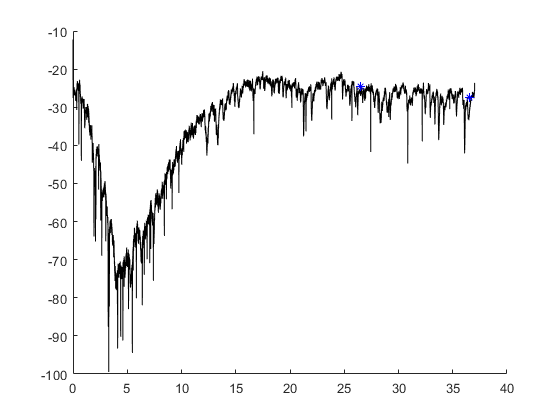

curChangeACSFcs3 = -2.9297

[curChangeACSFcs3] = currentAnalysisIHC(acsfcs3,time3_2,26.5,10)

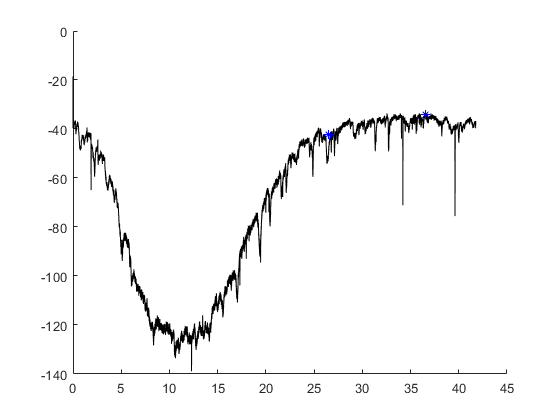

curChangeACSFcs4 = 8.2092

[curChangeACSFcs4] = currentAnalysisIHC(acsfcs4,time4_2,26.5,10)


curChangeACSFcs = [curChangeACSFcs1,curChangeACSFcs2,curChangeACSFcs3,curChangeACSFcs4]

curChangeACSFcs =    -1.8311    0.4730   -2.9297    8.2092



conditions = {'ACSF','MRS2500','Cs-TEA, MRS2500'};
ylbl = 'Change in holding current (pA)';
dim = [3 3];
compare3(curChangeACSF,curChangeMRS,curChangeMRScs,conditions,ylbl,dim);

p = 1.1396e-04

stats = struct with fields:
    gnames: {3×1 cell}
         n: [5 6 6]
    source: 'anova1'
     means: [-1.6083 -16.4795 -1.1266]
        df: 14
         s: 4.8894


c =     1.0000    2.0000    7.1222   14.8712   22.6202    0.0005
    1.0000    3.0000   -8.2306   -0.4817    7.2673    0.9855
    2.0000    3.0000  -22.7412  -15.3529   -7.9645    0.0002


gnames = 3×1 cell array
    {'ACSF' }
    {'MRS'  }
    {'MRScs'}


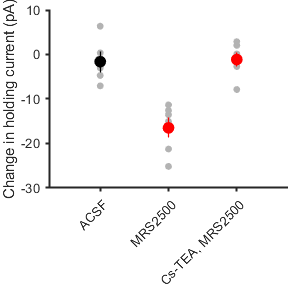

ylim([-30 10]);

%export_fig('.\EPS Panels\IHCCurChange.eps',gcf);  


conditions = {'+aCSF','+MRS2500','+aCSF','+MRS2500'};
h = compare4_2(curChangeACSF,curChangeMRS,curChangeACSFcs,curChangeMRScs,conditions,ylbl,dim,[10 15])

p = 5.1621e-05

stats = struct with fields:
    gnames: {4×1 cell}
         n: [5 6 4 6]
    source: 'anova1'
     means: [-1.6083 -16.4795 0.9804 -1.1266]
        df: 17
         s: 4.9134


c =     1.0000    2.0000    6.4141   14.8712   23.3284    0.0006
    1.0000    3.0000  -11.9577   -2.5887    6.7804    0.8600
    1.0000    4.0000   -8.9388   -0.4817    7.9755    0.9984
    2.0000    3.0000  -26.4752  -17.4599   -8.4445    0.0002
    2.0000    4.0000  -23.4164  -15.3529   -7.2893    0.0002
    3.0000    4.0000   -6.9084    2.1070   11.1223    0.9090


gnames = 4×1 cell array
    {'ACSF'  }
    {'MRS'   }
    {'ACSFcs'}
    {'MRScs' }


h =   Figure (223) with properties:

      Number: 223
        Name: ''
       Color: [1 1 1]
    Position: [0 0 2 3]
       Units: 'inches'

  Show all properties


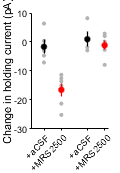

ylim([-30 10])
figQuality(gcf,gca,[0.75 1.8])
handleTheSubplot({h,h},[1 2]);

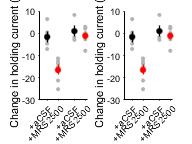

figQuality(gcf,gca,[2 1.5])
export_fig('.\EPS Panels\inward_currents.eps')


conditions = {'pre','post','pre','post','pre','post'};
ylbl3 = 'holding current (pA)';
compare6(baselineMaxACSF,endMaxACSF,baselineMaxMRS,endMaxMRS,baselineMaxcs,endMaxcs,conditions,ylbl3,dim)

    0.7838

    0.0028

    0.6986



ans = 0

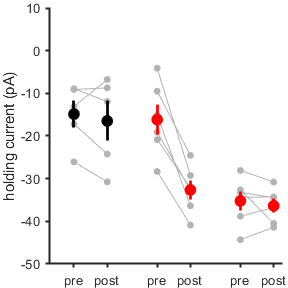

 ylim([-50 10])

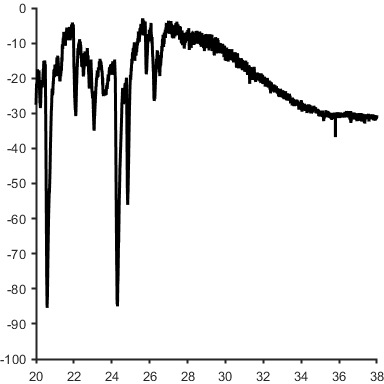

% generation of representative images

% K meth internal MRS 2500 application - #2 - application at 25, wash on at 26.5
figure
mrs2 = medfilt1(mrs2,200);
plot(time2()/60,mrs2(),'k','LineWidth', 2)
ylim([-100 0]);
xlim([20 38])
figQuality(gcf,gca,[4 4])

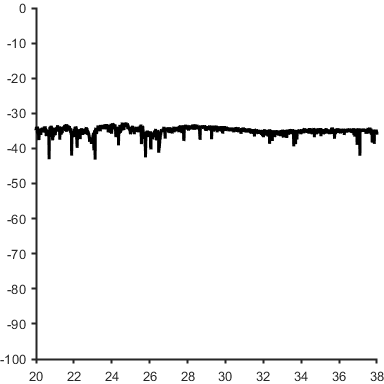


% cs-TEA internal mrs2500 application - #4 - Application at 25, wash on at 26.5
figure
mrscs3 = medfilt1(mrscs3,200);
plot(time3cs/60,mrscs3(),'k','LineWidth',2)
ylim([-100 0])
xlim([20 38])
figQuality(gcf,gca,[4 4])


% MRS2500 application, long recording (with baseline corrected for)
% MRS on at 13, off at 16.5 minutes
figure
[mrs6,time6] = loadPclampData('2018_11_01_0008_baseline.abf');

** abfload
opening 2018_11_01_0008_baseline.abf..
data were acquired in gap-free mode


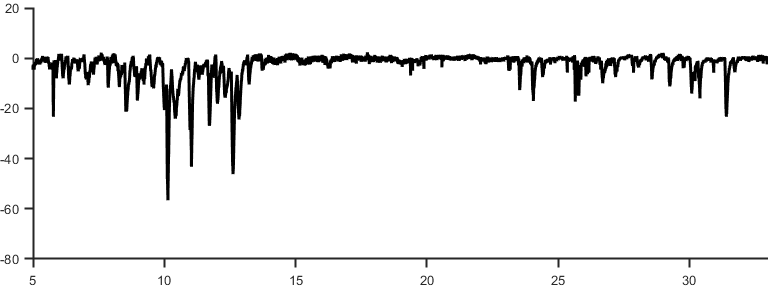

mrs6 = medfilt1(mrs6,200);
plot(time6/60,mrs6,'k','LineWidth',2)
ylim([-60 10])
xlim([5 33])
figQuality(gcf,gca,[8 3])

% P6-P8 WT FVB IHC recordings, apex, 2.5mM K+ external + MRS2500 application

[mrs1 time1] = loadPclampData('2018_05_19_0015 baseline adjusted MRS 19 min.abf');

** abfload
opening 2018_05_19_0015 baseline adjusted MRS 19 min.abf..
data were acquired in gap-free mode


[mrs2 time2] = loadPclampData('2018_05_23_0019_rawadjusted.abf');

** abfload
opening 2018_05_23_0019_rawadjusted.abf..
data were acquired in gap-free mode


[mrs3 time3] = loadPclampData('2018_05_30_0005_rawadjusted.abf');

** abfload
opening 2018_05_30_0005_rawadjusted.abf..
data were acquired in gap-free mode


[mrs4 time4] = loadPclampData('2018_06_14_0001 whole file adjusted.abf');

** abfload
opening 2018_06_14_0001 whole file adjusted.abf..
data were acquired in gap-free mode


[mrs5 time5] = loadPclampData('2018_06_14_0016 whole file adjusted.abf');

** abfload
opening 2018_06_14_0016 whole file adjusted.abf..
data were acquired in gap-free mode


[mrs6 time6] = loadPclampData('2018_07_01_0002_whole baseline adjusted.abf');

** abfload
opening 2018_07_01_0002_whole baseline adjusted.abf..
data were acquired in gap-free mode


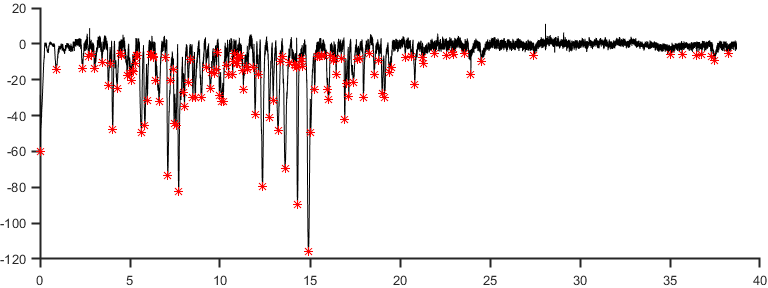

preFreq1 = 6.6000

postFreq1 = 1.4000

preAmp1 = -21.7039

postAmp1 = -9.2300


% Peakfinding fails here - inconsistent noise levels. may need to adjust function
% for sd of baseline noise in each trace. 
[preFreq1,postFreq1,preAmp1,postAmp1] = freqAmpIHC(mrs1,time1,19.5)

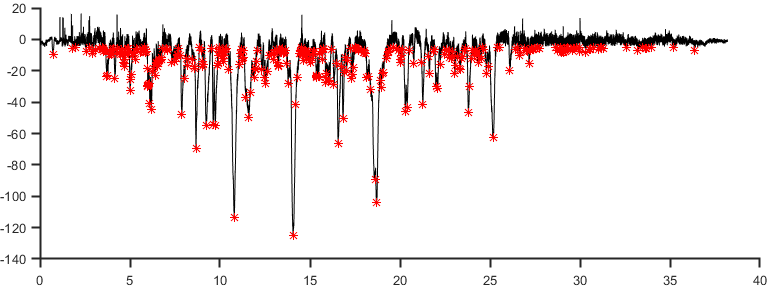

preFreq2 = 12

postFreq2 = 5.9000

preAmp2 = -16.4076

postAmp2 = -8.2174

[preFreq2,postFreq2,preAmp2,postAmp2] = freqAmpIHC(mrs2,time2,24.5)

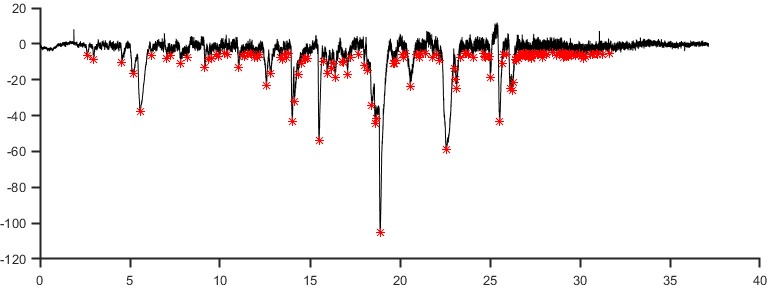

preFreq3 = 4.8000

postFreq3 = 5.7000

preAmp3 = -15.4842

postAmp3 = -7.1974

[preFreq3,postFreq3,preAmp3,postAmp3] = freqAmpIHC(mrs3,time3,26)

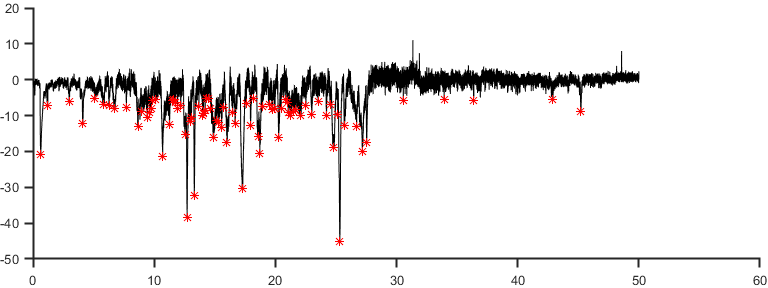

preFreq4 = 2.9000

postFreq4 = 0.5000

preAmp4 = -11.8533

postAmp4 = -10.9316

[preFreq4,postFreq4,preAmp4,postAmp4] = freqAmpIHC(mrs4,time4,27)

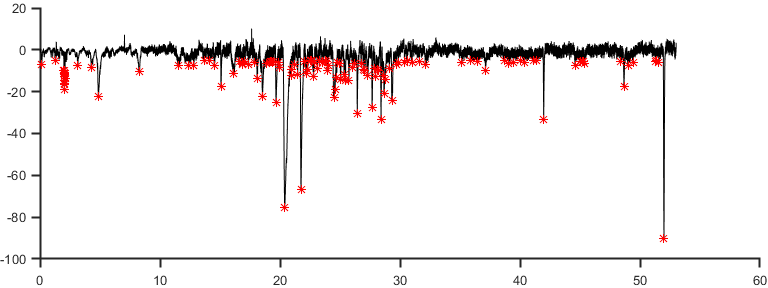

preFreq5 = 5.1000

postFreq5 = 1.4000

preAmp5 = -14.1360

postAmp5 = -6.2200

[preFreq5,postFreq5,preAmp5,postAmp5] = freqAmpIHC(mrs5,time5,29.5)

% [preFreq6,postFreq6,preAmp6,postAmp6] = freqAmpIHC(mrs6,time6,drugTime) lose cell before 10 minutes

preMRSFreq25 = [preFreq1,preFreq2,preFreq3,preFreq4,preFreq5];
postMRSFreq25 = [postFreq1,postFreq2,postFreq3,postFreq4,postFreq5];
preMRSAmp25 = abs([preAmp1,preAmp2,preAmp3,preAmp4,preAmp5]);
postMRSAmp25 = abs([postAmp1,postAmp2,postAmp3,postAmp4,postAmp5]);

conditions = {'baseline','MRS2500'};
ylbl1 = 'Events per minute';
ylbl2 = 'Mean amplitude (-pA)';
dim = [2 3];
[hFreq pFreq] =compare2(preMRSFreq25,postMRSFreq25,conditions,ylbl1,dim);

    0.0546



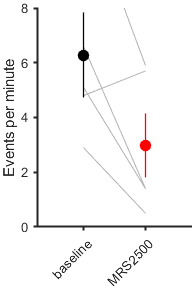

 ylim([0 8]);

%export_fig('.\EPS Panels\IHCMRSFreq25.eps',gcf);  

[hAmp pAmp] =compare2(preMRSAmp25,postMRSAmp25,conditions,ylbl2,dim);

    0.0153



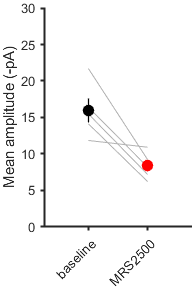

 ylim([0 30]);

%export_fig('.\EPS Panels\IHCMRSAmp25',gcf);  


% Hair cells in P2rY1 KO